**ASSIGNMENT-8**

**P. SAI UTTEJ**

**19BCE7163**

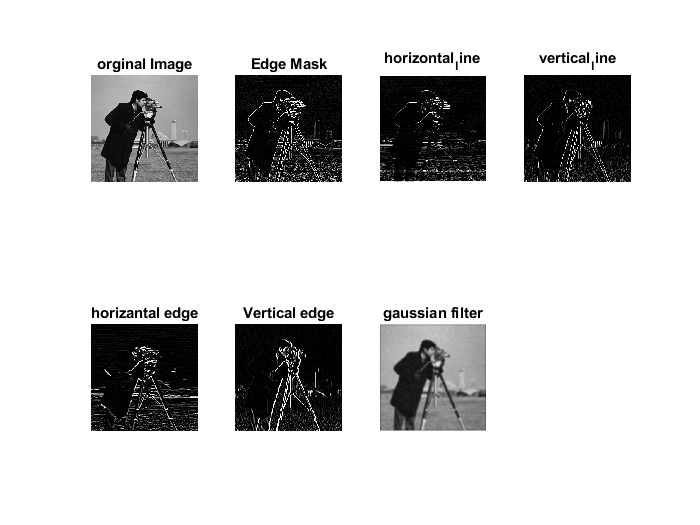


img=imread('cameraman.tif');%reading cameraman image and loading into variable img
subplot(2,4,1) ,imshow(img);   %displaying img's image
title('orginal Image')
[m,n]=size(img);             %initializing the size of image into m and n variables
imgpad = zeros(258,258);     %assigning the imgpad to zeros 258 rows and 258 coloumns .
imgpad(2:257,2:257)=img;


edgemask=[-1 -1 -1 ;-1 8 -1;-1 -1 -1];
op=convulution_user(imgpad,m,n,edgemask);
subplot(2,4,2),imshow(uint8(op));
title('Edge Mask')


line_de_ho=[-1 -1 -1 ;2 2 2;-1 -1 -1];
op=convulution_user(imgpad,m,n,line_de_ho);
subplot(2,4,3), imshow(uint8(op));
title('horizontal_line')


line_de_ho=[-1 2 -1 ;-1 2 -1;-1 2 -1];
op=convulution_user(imgpad,m,n,line_de_ho);
subplot(2,4,4) , imshow(uint8(op));
title('vertical_line')

horiz_edge=[-1 -2 -1 ;-0 0 0;1 2 1];
op=convulution_user(imgpad,m,n,horiz_edge);
subplot(2,4,5) , imshow(uint8(op));
title('horizantal edge')

horiz_edge=[-1 0 1 ;-2 0 2;-1 0 1];
op=convulution_user(imgpad,m,n,horiz_edge);
subplot(2,4,6) , imshow(uint8(op));
title('Vertical edge')

%GAUSSIAN FILTER
Img = imread('cameraman.tif');
A = imnoise(Img,'Gaussian',0.04,0.003);
%Image with noise
I = double(A);

%Design the Gaussian Kernel
%Standard Deviation
sigma = 1.76;
%Window size
sz = 4;
[x,y]=meshgrid(-sz:sz,-sz:sz);

M = size(x,1)-1;
N = size(y,1)-1;
Exp_comp = -(x.^2+y.^2)/(2*sigma*sigma);
Kernel= exp(Exp_comp)/(2*pi*sigma*sigma);
Output=zeros(size(I));
%Pad the vector with zeros
I = padarray(I,[sz sz]);

%Convolution
for i = 1:size(I,1)-M
    for j =1:size(I,2)-N
        Temp = I(i:i+M,j:j+M).*Kernel;
        Output(i,j)=sum(Temp(:));
    end
end
%Image without Noise after Gaussian blur
Output = uint8(Output);
subplot(2,4,7),imshow(Output);
title("gaussian filter")